% Elastic Net Regularization
clc, clearvars, close all;
data = readtable("C:\Users\prajw\OneDrive - Amrita Vishwa Vidyapeetham\Desktop\Sem3\MFC3\Lasso-and-Ridge-Regression-using-ADMM\melb_data.csv");

%Filling missing values for the column Car
car_mode = mode(data.Car(~isnan(data.Car))); 
data.Car(isnan(data.Car)) = car_mode;        

%Filling missing values for the column Building Area
uniqueRooms = unique(data.Rooms);
for i = 1:length(uniqueRooms);
    r = uniqueRooms(i);
    rowsInGroup = data.Rooms == r;
    medianBA = median(data.BuildingArea(rowsInGroup & ~isnan(data.BuildingArea)));
    missingBA = isnan(data.BuildingArea) & rowsInGroup;
    data.BuildingArea(missingBA) = medianBA;
end

%Filling missing values for the column Year Built
uniquesuburb = unique(data.Suburb);
for i =1:length(uniquesuburb)
    s = uniquesuburb{i};
    rowsinsuburb = strcmp(data.Suburb, s);
    medianYB = median(data.YearBuilt(rowsinsuburb & ~isnan(data.YearBuilt)));
    missingYB = isnan(data.YearBuilt) & rowsinsuburb;
    data.YearBuilt(missingYB) = medianYB;
end

sum(isnan(data.YearBuilt));
%Here 18 values came so we need to fill the remaining by taking the overall median over the column

globalMedianYB = median(data.YearBuilt, 'omitnan');
data.YearBuilt(isnan(data.YearBuilt)) = globalMedianYB;

%Filling missing values for the column CouncilArea
suburbList = unique(data.Suburb);
for i = 1:length(suburbList)
    s = uniquesuburb{i};
    rowsinsuburb = strcmp(data.Suburb, s);
    knownCouncilAreas = data.CouncilArea(rowsinsuburb & ~ismissing(data.CouncilArea));
    if ~isempty(knownCouncilAreas)
        modeCouncil = mode(categorical(knownCouncilAreas));
        missingIdx = rowsinsuburb & ismissing(data.CouncilArea);
        data.CouncilArea(missingIdx) = cellstr(modeCouncil);
    end
end
sum(ismissing(data.CouncilArea)); %Here 7 were missing so take the global mode
globalMode = mode(categorical(data.CouncilArea(~ismissing(data.CouncilArea))));
data.CouncilArea(ismissing(data.CouncilArea)) = cellstr(globalMode);

% Removing unimportant features
data.Address  = []; 
data.Date = []; 
data.SellerG = []; 

% Split original data before one-hot encoding
numericCols = {'Rooms', 'Price', 'Distance', 'Postcode', 'Bedroom2', ...
               'Bathroom', 'Car', 'Landsize', 'BuildingArea', 'YearBuilt', 'Lattitude', 'Longtitude','Propertycount'};

% Loop through each column and apply z-score normalization
for i = 1:length(numericCols)
    colName = numericCols{i};
    colData = data.(colName);
    mu = mean(colData);
    sigma = std(colData);

    % Avoid division by zero in case of zero std deviation
    if sigma ~= 0
        data.(colName) = (colData - mu) / sigma;
    else
        data.(colName) = zeros(size(colData)); % If std is 0, set to zero vector
    end
end

dummyVars = {};
todo = {'Suburb', 'Type', 'Method', 'CouncilArea', 'Regionname'};

for i = 1:length(todo)
    colName = todo{i};
    catVar = categorical(data.(colName));
    encoded = dummyvar(catVar);
    dummyVars{end+1} = encoded;
    data.(colName) = [];
end

oneHotEncodedMatrix = cat(2, dummyVars{:});

numericpart = table2array(data(:,1:end-1));
target = table2array(data(:,end));

data = [numericpart,oneHotEncodedMatrix,target];

A = data(:,1:end-1);
b = data(:,end);

g = size(A, 1);
split_index = round(0.7 * g);
A_train = A(1:split_index, :);
A_test  = A(split_index+1:end, :);
b_train = b(1:split_index, :);
b_test  = b(split_index+1:end, :);

lambda1 = 0.1;
lambda2 = 0.05;
rho = 1.6;
max_iter = 3000;
tol  = 1e-4;

function [x,history] = elasticnet_admm(A,b,lambda1,lambda2,rho,max_iter,tol)
    [m, n] = size(A);
    z0 = zeros(n, 1);
    u0 = zeros(n, 1);
    AtA = A'*A;
    Atb = A'*b;
    I = eye(n);
    i = 1;

    history.objval = zeros(max_iter,1);
    history.primal_res = zeros(max_iter,1);
    history.dual_res = zeros(max_iter,1);

    while i < max_iter
        % x-update
        x1 = (AtA + rho*I) \ (Atb + rho*(z0 - u0));

        % z-update (soft thresholding for L1)
        z_tilde = x1 + u0;
        gamma = rho / (rho + 2*lambda2);
        tau   = lambda1 / rho;
        z1 = gamma * soft_threshold(z_tilde, tau);

        % u-update
        u1 = u0 + (x1 - z1);

        % diagnostics
        r_norm = norm(x1 - z1);
        s_norm = norm(rho*(z1 - z0));

        history.objval(i) = 0.5*norm(A*x1-b)^2 + ...
                            lambda1*norm(z1,1) + lambda2*norm(z1,2)^2;
        history.primal_res(i) = r_norm;
        history.dual_res(i) = s_norm;

        % stopping criteria
        if (r_norm <= tol && s_norm <= tol)
            fprintf("Converged at %dth iteration\n", i)
            history.objval = history.objval(1:i);
            history.primal_res = history.primal_res(1:i);
            history.dual_res = history.dual_res(1:i);
            break
        end

        % update
        z0 = z1;
        u0 = u1;
        i = i + 1;
    end
    x = x1;
end

function z = soft_threshold(x, tau)
    z = sign(x) .* max(abs(x) - tau, 0);
end

[x,history] = elasticnet_admm(A_train,b_train,lambda1,lambda2,rho,max_iter,tol);

Converged at 80th iteration


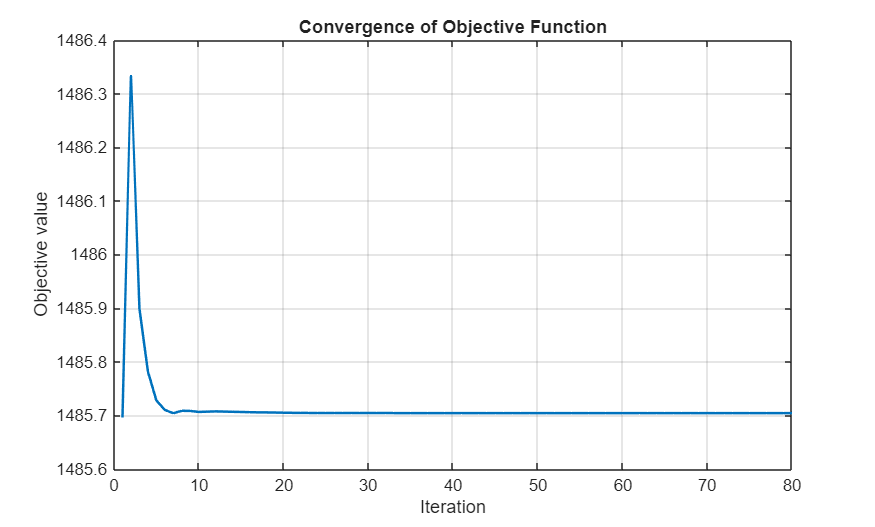

% Plot objective value
figure;
plot(history.objval, 'LineWidth', 1.5);
xlabel('Iteration');
ylabel('Objective value');
title('Convergence of Objective Function');
grid on;

y = A_test * x;
rmse = sqrt(mean((y - b_test).^2));
mae = mean(abs(y - b_test));
disp(['RMSE: ', num2str(rmse)]);

RMSE: 0.72075


disp(['MAE: ', num2str(mae)]);

MAE: 0.3882
